datapath = ...
    {"/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221122_DAsensorHEK001/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221122_DAsensorHEK002/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221122_5HTsensorHEK001/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/0729NEsensorHEK001",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/0801iAchHEK001",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/yc5HTSensor008(HEK_5HTSensor_5HT)-Analyzed/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/yc5HTSensor009(HEK_5HTSensor_5HT)-Analyzed/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221206NEsensorHEK001/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221206NEsensorHEK002/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/202212065HTsensorHEK001/"...
    }

datapath = 1×7 cell array
    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221122_DAsensorHEK001/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221122_DAsensorHEK002/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/20221122_5HTsensorHEK001/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/0729NEsensorHEK001"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/0801iAchHEK001"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/yc5HTSensor008(HEK_5HTSensor_5HT)-Analyzed/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Other_NM_sensors/yc5HTSensor009(HEK_5HTSensor_5HT)-Analyzed/"]}




StateYao_file = ...
    {"analysis_offset0_20221130.mat",...
    "analysis_offset0_ROIadjusted_20221201.mat",...
    "analysis_offset0_ROIadjusted_20221201.mat",...
    "analysis_offset0_ROIadjusted_20221202.mat",...
    "analysis_20221121/analysis_20221121.mat",...
    "Analysis_PM_offset0/yc5HTSensor008_Analysis2022-11-09.mat",...
    "Analysis_PM_offset0/yc5HTSensor009_Analysis2022-11-09.mat",...
    "analysis_offset0_20221207.mat",...
    "analysis_offset0_20221207.mat",...
    "analysis_offset0_20221207.mat"...
    }

StateYao_file = 1×7 cell array
    {["analysis_offset0_20221130.mat"]}    {["analysis_offset0_ROIadjusted_20221201.mat"]}    {["analysis_offset0_ROIadjusted_20221201.mat"]}    {["analysis_offset0_ROIadjusted_20221202.mat"]}    {["analysis_20221121/analysis_20221121.mat"]}    {["Analysis_PM_offset0/yc5HTSensor008_Analysis2022-11-09.mat"]}    {["Analysis_PM_offset0/yc5HTSensor009_Analysis2022-11-09.mat"]}


all_epochs = [2 3 4]; % all the epochs
drug_epochs = [2 3 4];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

% CyclePositions = [1 2 3]; % which cycle positions we want to analyze
baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

i = 1;

cd(datapath{i});
load(StateYao_file{i});

CyclePositions = 1:1:size(stateYao.CyclePositions, 2)

CyclePositions =      1     2     3


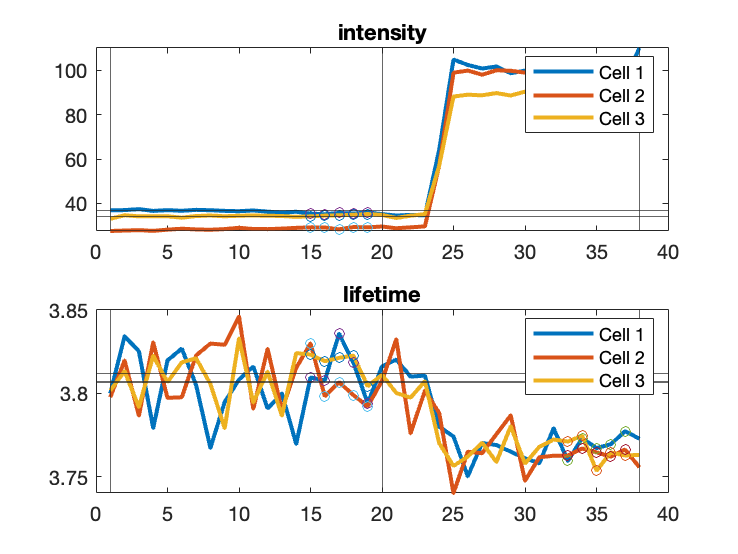

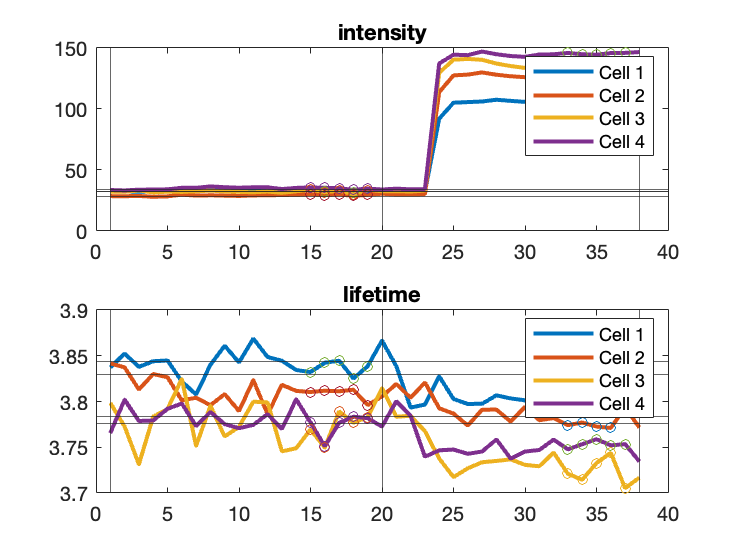

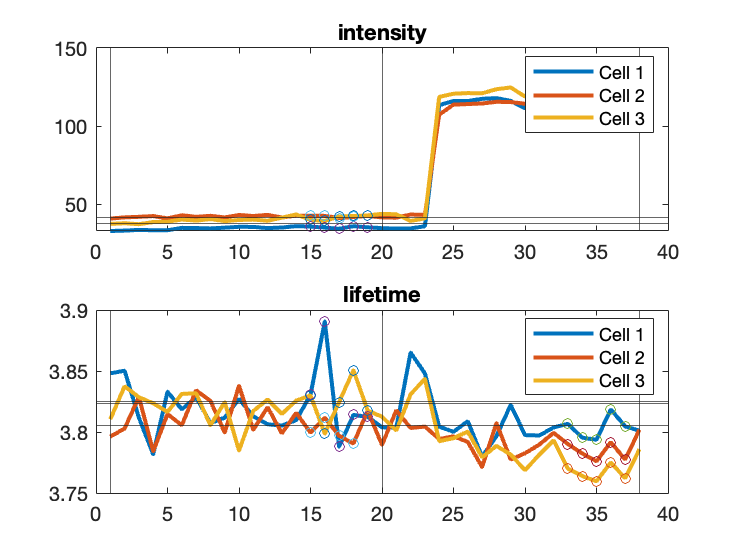

epoch_response_intensity_norm_all = 1×3 cell array
    {2×3 double}    {2×4 double}    {2×3 double}


epoch_response_lft_norm_all = 1×3 cell array
    {2×3 double}    {2×4 double}    {2×3 double}


epoch_response_intensity_all = 1×3 cell array
    {2×3 double}    {2×4 double}    {2×3 double}


epoch_response_lft_all = 1×3 cell array
    {2×3 double}    {2×4 double}    {2×3 double}



% Yao_GUI_ReviseROIsBasedOnCoordinates()
CalculateROIBasedOnTopPixels(5, 0.66)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels();
[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

i = 2;

cd(datapath{i});
load(StateYao_file{i});

CyclePositions = 1:1:size(stateYao.CyclePositions, 2)

CyclePositions =      1     2     3


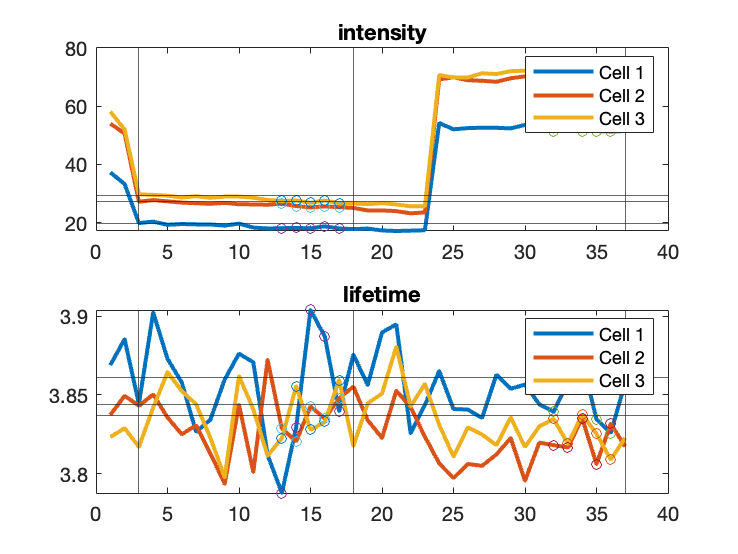

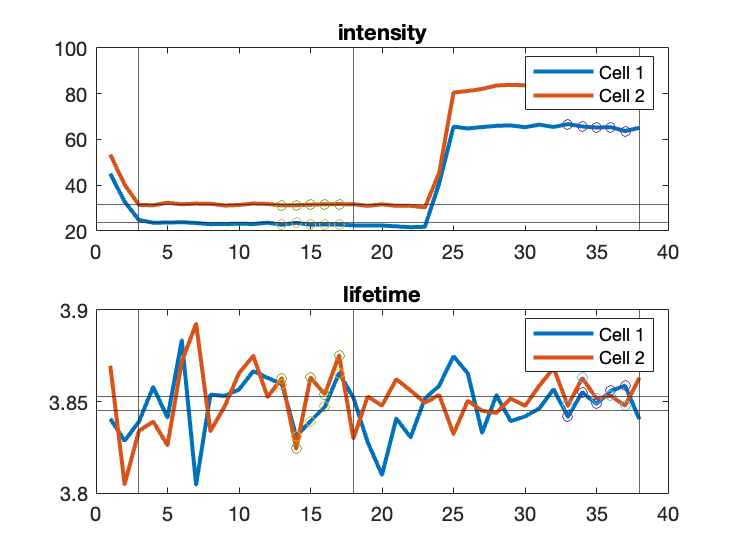

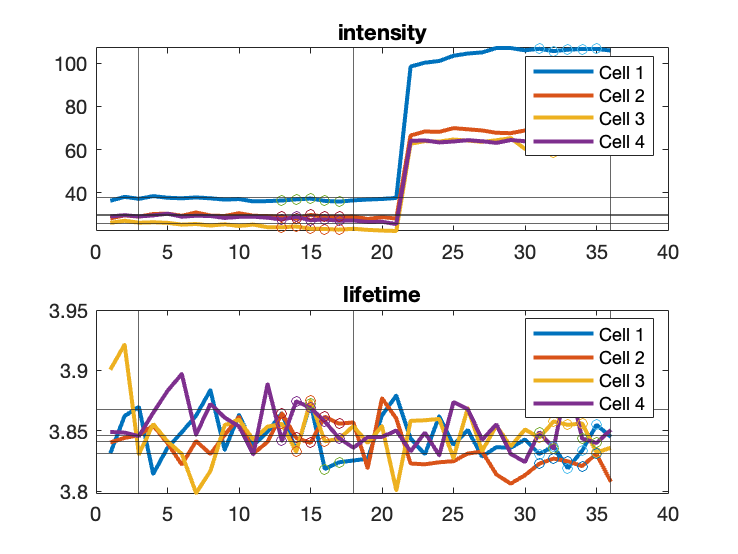

epoch_response_intensity_norm_all = 1×3 cell array
    {2×3 double}    {2×2 double}    {2×4 double}


epoch_response_lft_norm_all = 1×3 cell array
    {2×3 double}    {2×2 double}    {2×4 double}


epoch_response_intensity_all = 1×3 cell array
    {2×3 double}    {2×2 double}    {2×4 double}


epoch_response_lft_all = 1×3 cell array
    {2×3 double}    {2×2 double}    {2×4 double}



% Yao_GUI_ReviseROIsBasedOnCoordinates()
CalculateROIBasedOnTopPixels(5, 0.66)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels();
[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)


projection_37 = spc.projects{1};
lftMap_37 = spc.lifetimeMaps{1};
imageMods_37 = spc.imageMods{1,1};


% raw mask
mask_37 = stateYao.images.I_ROI_stack{1}{13,1}(:,:,1);
lft_37 = Yao_calc_Lifetime(projection_37,lftMap_37, mask_37)

lft_37 = 3.8234

% with thresholding of 5
mask_37_threshold = mask_37;

for i = 1:128
    for j = 1:128
        if mask_37(i,j) ==1
            if projection_37(i,j) <=5
                mask_37_threshold(i,j) = 0;
            end
        end
    end
end

lft_37_thresholded = Yao_calc_Lifetime(projection_37,lftMap_37, mask_37_threshold)

lft_37_thresholded = 3.8117

% top pixels
mask_37_topPixel = stateYao.I_ROI_stack_TopPixels{1,1}{1,13}{1,1};
lft_37_topPixel = Yao_calc_Lifetime(projection_37,lftMap_37, mask_37_topPixel)

lft_37_topPixel = 3.7877

histogram_toppixels_37 = zeros(256,1);

for i = 1:128
    for j = 1:128
        if mask_37_topPixel(i,j) ==1
            histogram_toppixels_37 = histogram_toppixels_37 + imageMods_37(:,i,j);
        end
    end
end

histogram_toppixels_37_norm = histogram_toppixels_37/max(histogram_toppixels_37);

mask_37_nontop = zeros(128,128);

for i = 1:128
    for j = 1:128
        if mask_37(i,j) ==1
            if mask_37_topPixel(i,j) == 0
                mask_37_nontop(i,j) = 1;
            end
        end
    end
end

lft_37_NontopPixel = Yao_calc_Lifetime(projection_37,lftMap_37, mask_37_nontop)

lft_37_NontopPixel = 3.8976


projection_43 = spc.projects{1};
lftMap_43 = spc.lifetimeMaps{1};
imageMods_43 = spc.imageMods{1,1};


% raw mask
mask_43 = stateYao.images.I_ROI_stack{1}{15,1}(:,:,1);
lft_43 = Yao_calc_Lifetime(projection_43,lftMap_43, mask_43)

lft_43 = 3.8841

% with thresholding of 5
mask_43_threshold = mask_43;

for i = 1:128
    for j = 1:128
        if mask_43(i,j) ==1
            if projection_43(i,j) <=5
                mask_43_threshold(i,j) = 0;
            end
        end
    end
end

lft_43_thresholded = Yao_calc_Lifetime(projection_43,lftMap_43, mask_43_threshold)

lft_43_thresholded = 3.8803

% top pixels
mask_43_topPixel = stateYao.I_ROI_stack_TopPixels{1,1}{1,15}{1,1};
lft_43_topPixel = Yao_calc_Lifetime(projection_43,lftMap_43, mask_43_topPixel)

lft_43_topPixel = 3.9040

histogram_toppixels_43 = zeros(256,1);

for i = 1:128
    for j = 1:128
        if mask_43_topPixel(i,j) ==1
            histogram_toppixels_43 = histogram_toppixels_43 + imageMods_43(:,i,j);
        end
    end
end

histogram_toppixels_43_norm = histogram_toppixels_43/max(histogram_toppixels_43);

mask_43_nontop = zeros(128,128);

for i = 1:128
    for j = 1:128
        if mask_43(i,j) ==1
            if mask_43_topPixel(i,j) == 0
                mask_43_nontop(i,j) = 1;
            end
        end
    end
end

lft_43_NontopPixel = Yao_calc_Lifetime(projection_43,lftMap_43, mask_43_nontop)

lft_43_NontopPixel = 3.8403

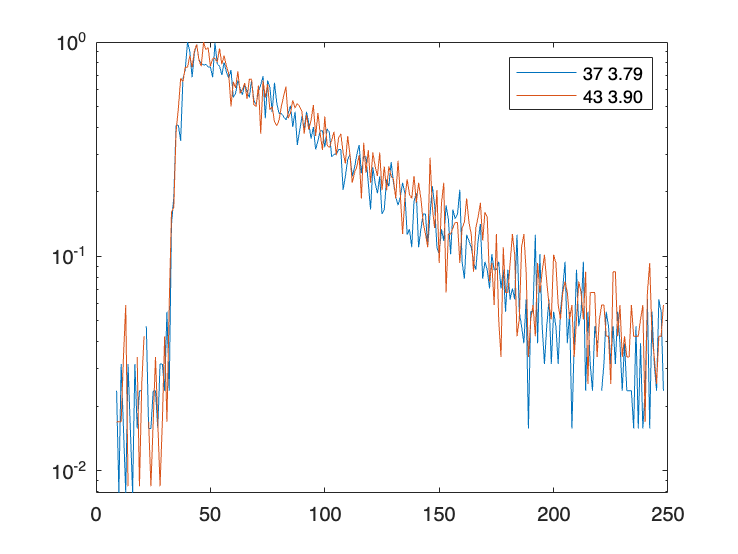

figure
semilogy(histogram_toppixels_37_norm)
hold on
semilogy(histogram_toppixels_43_norm)
legend('37 3.79','43 3.90')

sum(histogram_toppixels_37)

ans = 7273

sum(histogram_toppixels_43)

ans = 7235

i = 3;

cd(datapath{i});
load(StateYao_file{i});

CyclePositions = 1:1:size(stateYao.CyclePositions, 2)

CyclePositions =      1     2



% Yao_GUI_ReviseROIsBasedOnCoordinates()
CalculateROIBasedOnTopPixels(5, 0.66)

Cycle position 1, cell 1 in image 1, mask is empty.
Cycle position 1, cell 3 in image 1, mask is empty.
Cycle position 1, cell 1 in image 2, mask is empty.
Cycle position 1, cell 3 in image 2, mask is empty.
Cycle position 2, cell 2 in image 1, mask is empty.
Cycle position 2, cell 3 in image 1, mask is empty.
Cycle position 2, cell 4 in image 1, mask is empty.
Cycle position 2, cell 2 in image 2, mask is empty.
Cycle position 2, cell 3 in image 2, mask is empty.
Cycle position 2, cell 4 in image 2, mask is empty.


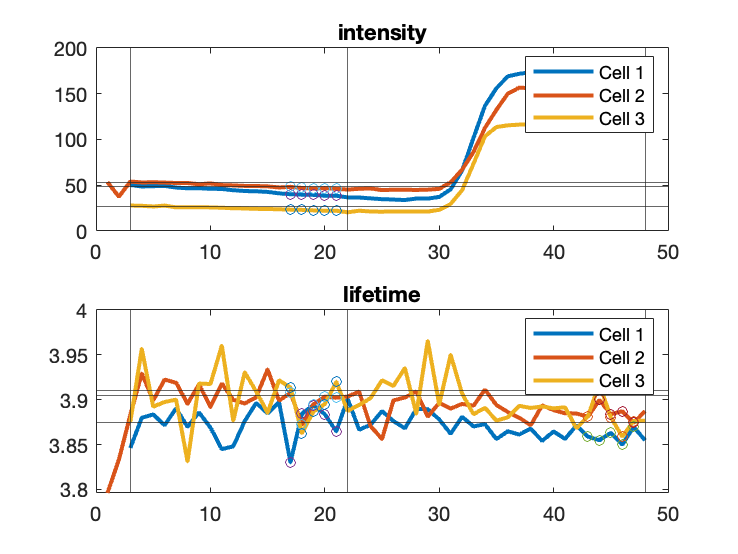

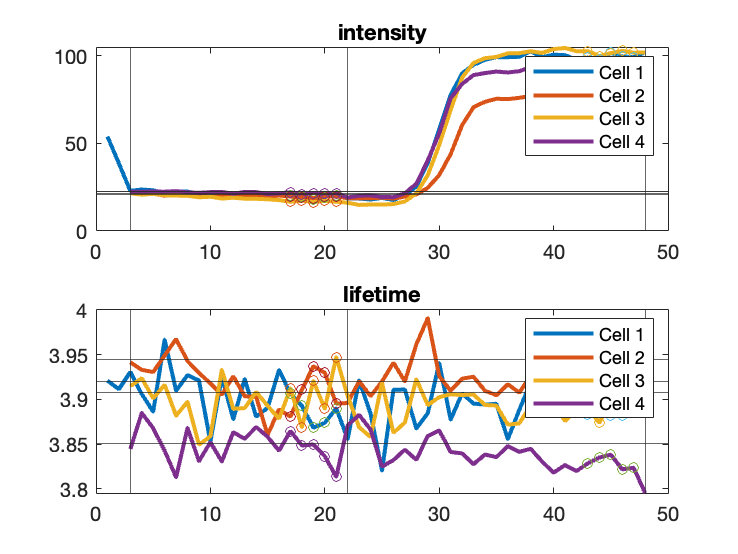

epoch_response_intensity_norm_all = 1×2 cell array
    {2×3 double}    {2×4 double}


epoch_response_lft_norm_all = 1×2 cell array
    {2×3 double}    {2×4 double}


epoch_response_intensity_all = 1×2 cell array
    {2×3 double}    {2×4 double}


epoch_response_lft_all = 1×2 cell array
    {2×3 double}    {2×4 double}


[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels();
[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

i = 4;

all_epochs = [2 3 4 5]; % all the epochs
drug_epochs = [2 3 4 5];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)
cd(datapath{i});
load(StateYao_file{i});

CyclePositions = 1:1:size(stateYao.CyclePositions, 2)

CyclePositions =      1     2


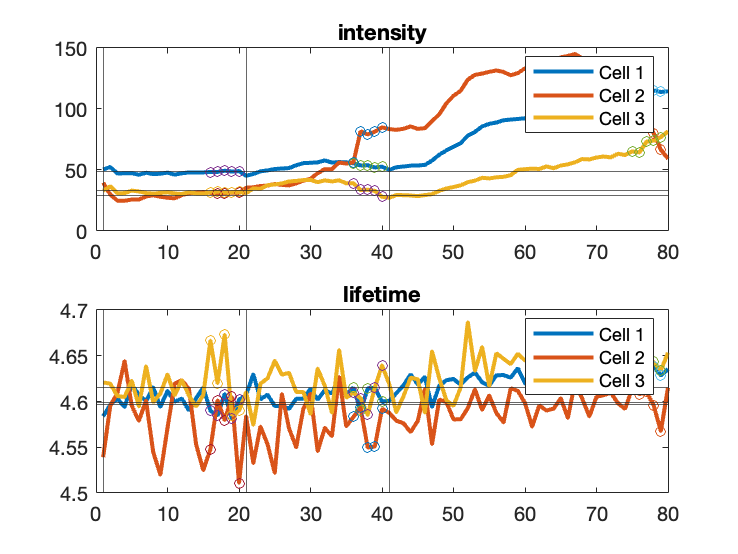

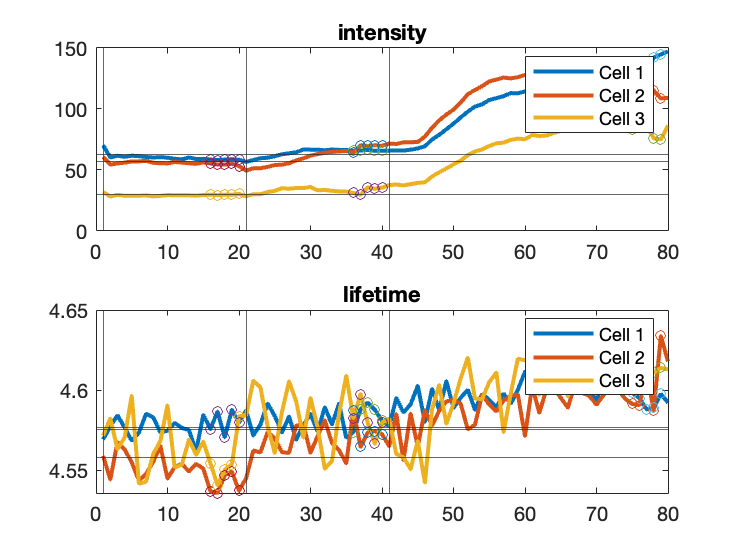

epoch_response_intensity_norm_all = 1×2 cell array
    {3×3 double}    {3×3 double}


epoch_response_lft_norm_all = 1×2 cell array
    {3×3 double}    {3×3 double}


epoch_response_intensity_all = 1×2 cell array
    {3×3 double}    {3×3 double}


epoch_response_lft_all = 1×2 cell array
    {3×3 double}    {3×3 double}



% Yao_GUI_ReviseROIsBasedOnCoordinates()
CalculateROIBasedOnTopPixels(5, 0.66)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels();
[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

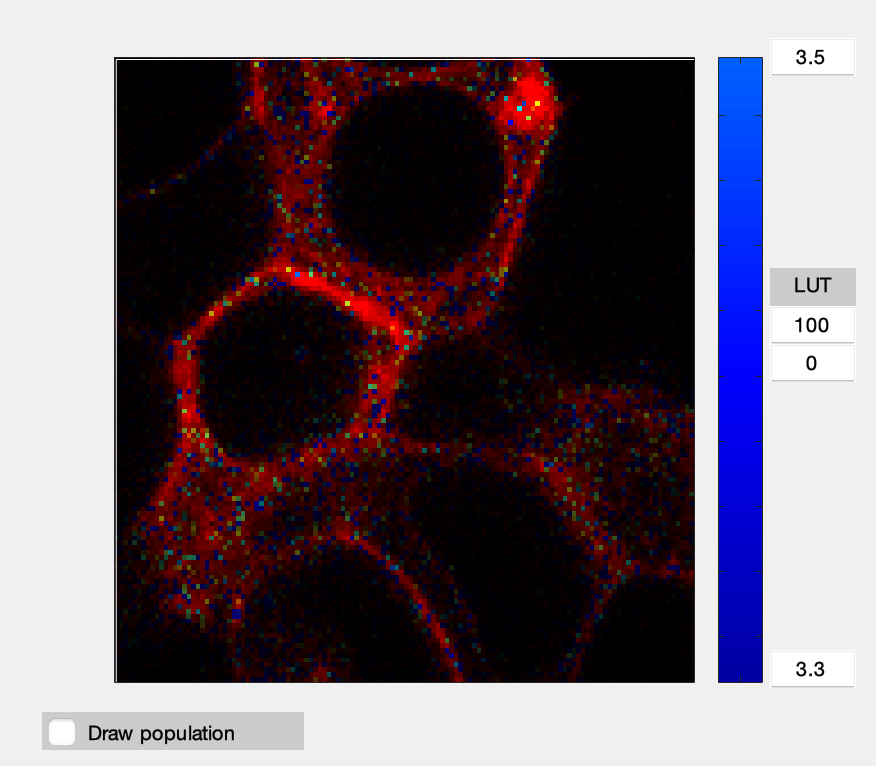

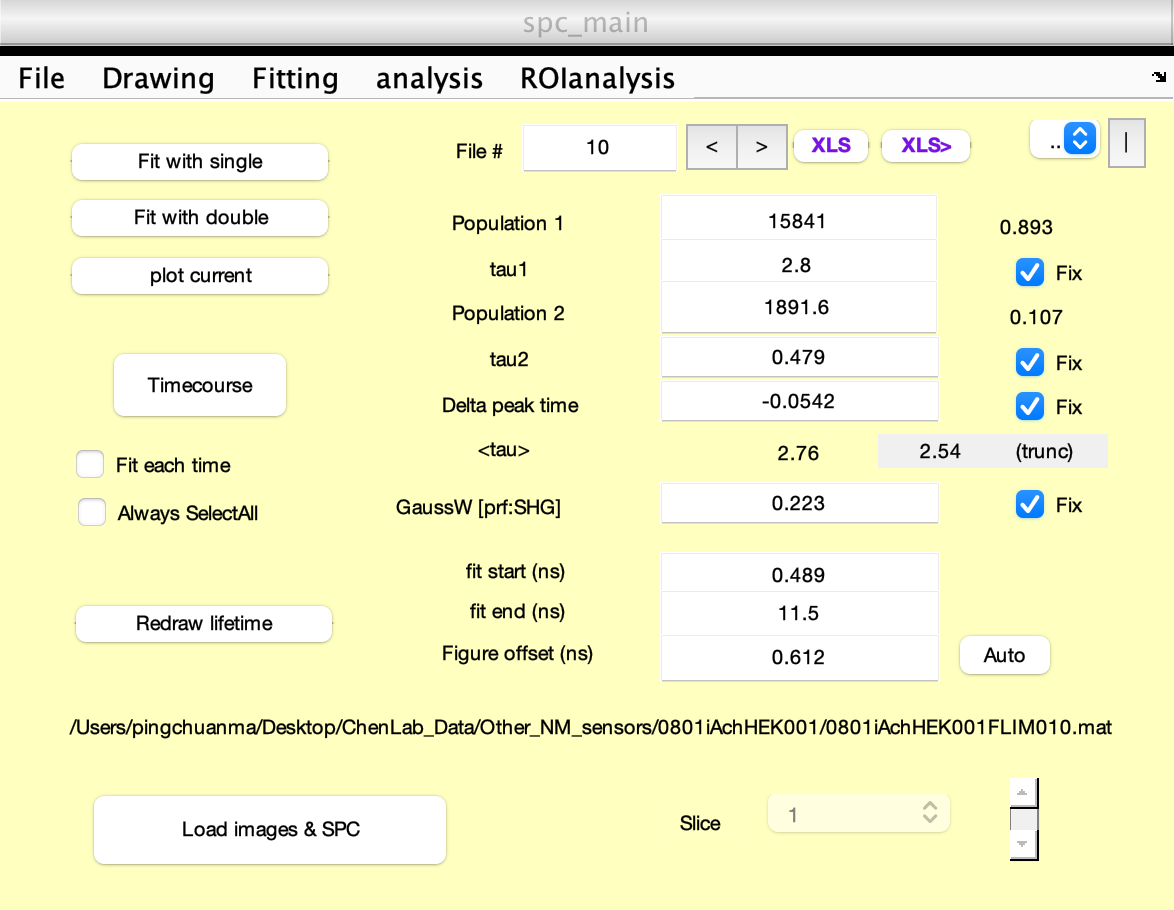

i = 5;

cd(datapath{i});
load(StateYao_file{i});


CyclePositions = 1:1:size(stateYao.CyclePositions, 2)

CyclePositions =      1     2


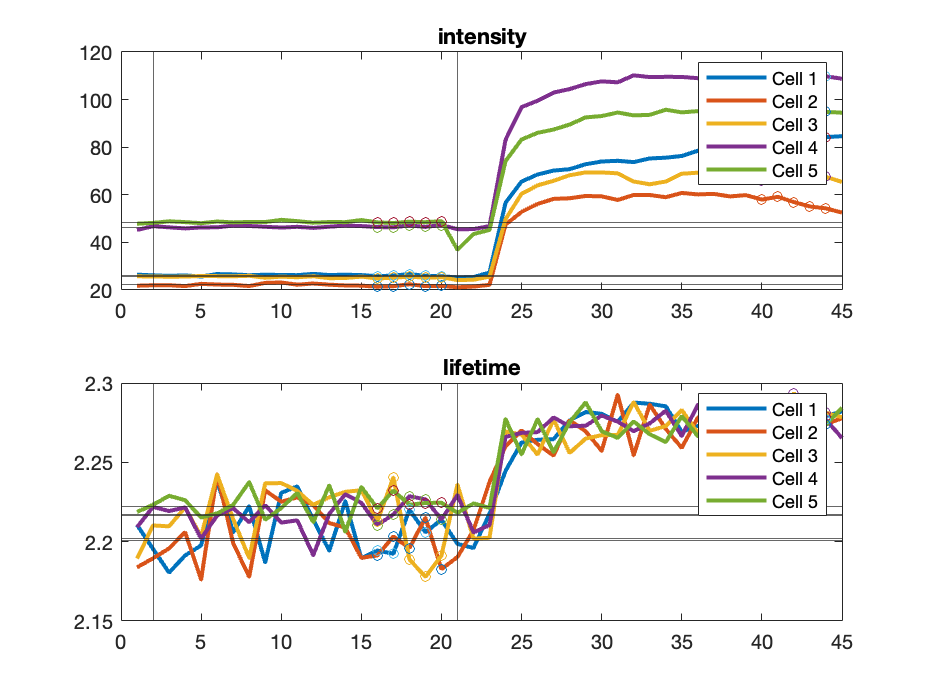

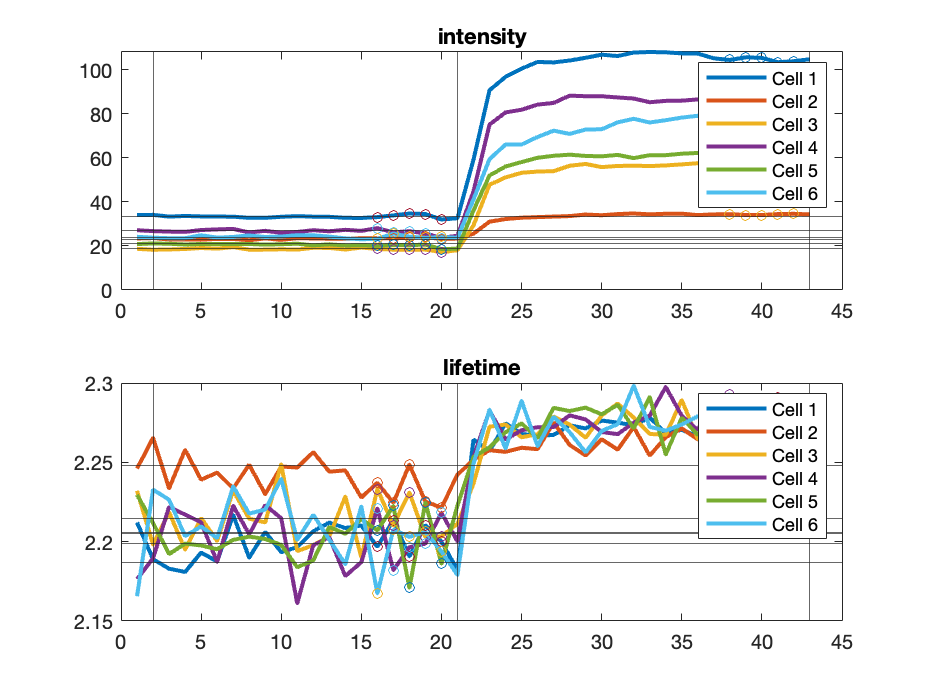

epoch_response_intensity_norm_all = 1×2 cell array
    {2×5 double}    {2×6 double}


epoch_response_lft_norm_all = 1×2 cell array
    {2×5 double}    {2×6 double}


epoch_response_intensity_all = 1×2 cell array
    {2×5 double}    {2×6 double}


epoch_response_lft_all = 1×2 cell array
    {2×5 double}    {2×6 double}



% Yao_GUI_ReviseROIsBasedOnCoordinates()
CalculateROIBasedOnTopPixels(5, 0.66)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels();
[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

i = 6;

all_epochs = [2 3 4 5]; % all the epochs
drug_epochs = [2 3 4 5];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

cd(datapath{i});
load(StateYao_file{i});

CyclePositions = 1:1:size(stateYao.CyclePositions, 2)

CyclePositions =      1     2     3


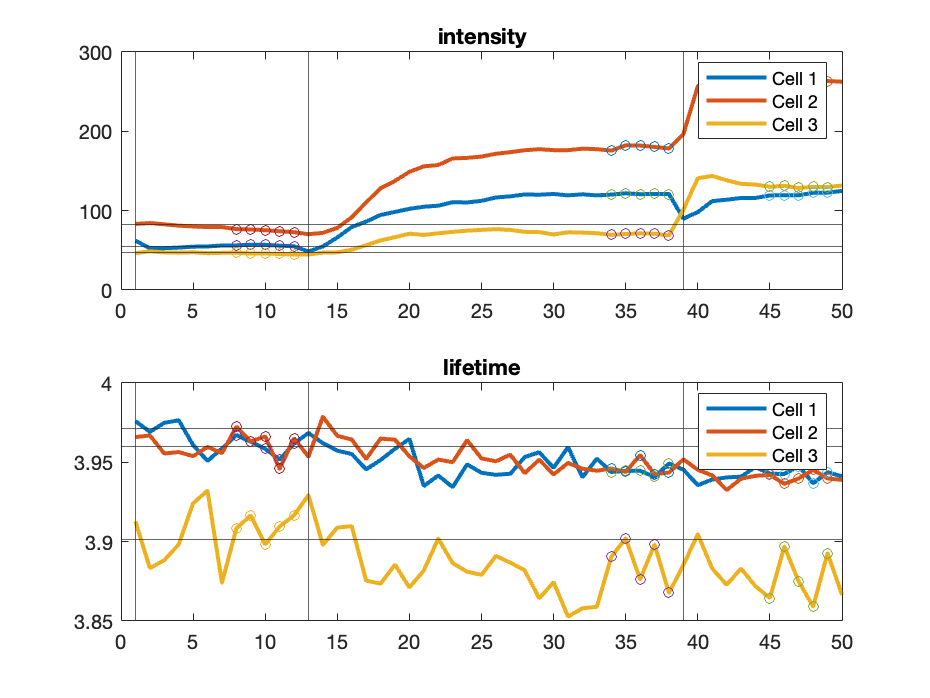

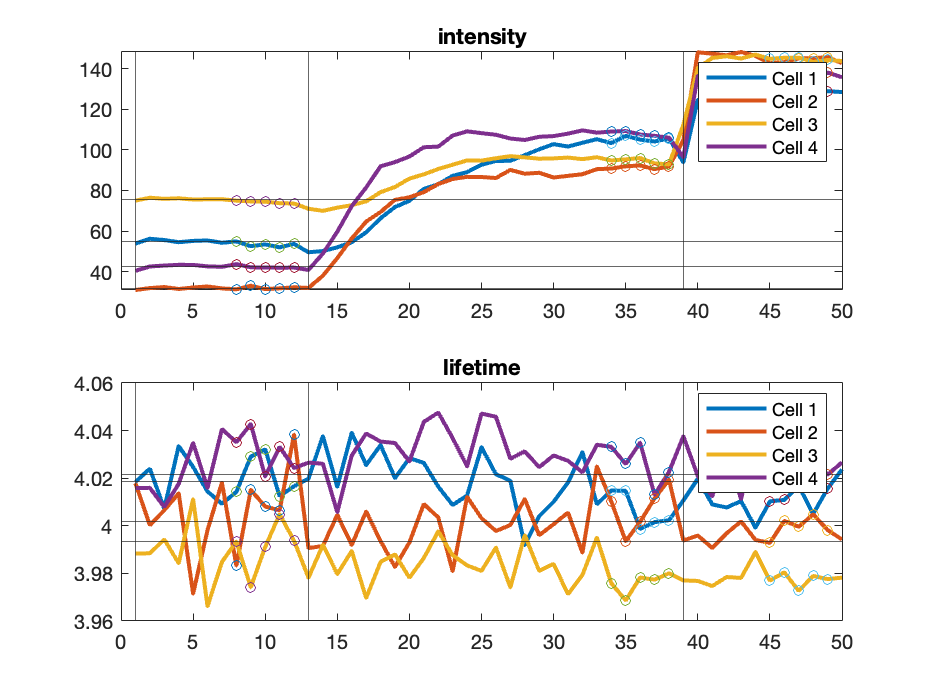

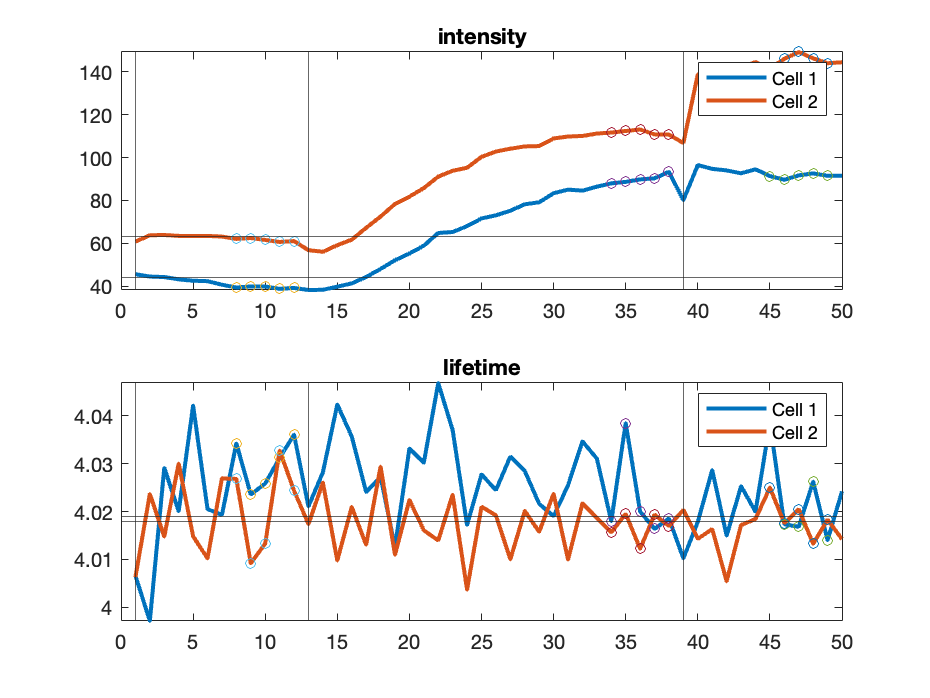

epoch_response_intensity_norm_all = 1×3 cell array
    {3×3 double}    {3×4 double}    {3×2 double}


epoch_response_lft_norm_all = 1×3 cell array
    {3×3 double}    {3×4 double}    {3×2 double}


epoch_response_intensity_all = 1×3 cell array
    {3×3 double}    {3×4 double}    {3×2 double}


epoch_response_lft_all = 1×3 cell array
    {3×3 double}    {3×4 double}    {3×2 double}



Yao_GUI_ReviseROIsBasedOnCoordinates()
CalculateROIBasedOnTopPixels(5, 0.66)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels();
EpochStartAcq_all{1} = EpochStartAcq1;
EpochStartAcq_all{2} = EpochStartAcq2;
EpochStartAcq_all{3} = EpochStartAcq3;

[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

i = 7;

all_epochs = [2 3 4]; % all the epochs
drug_epochs = [2 3 4];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

cd(datapath{i});
load(StateYao_file{i});

CyclePositions = 1:1:size(stateYao.CyclePositions, 2)

CyclePositions =      1     2     3


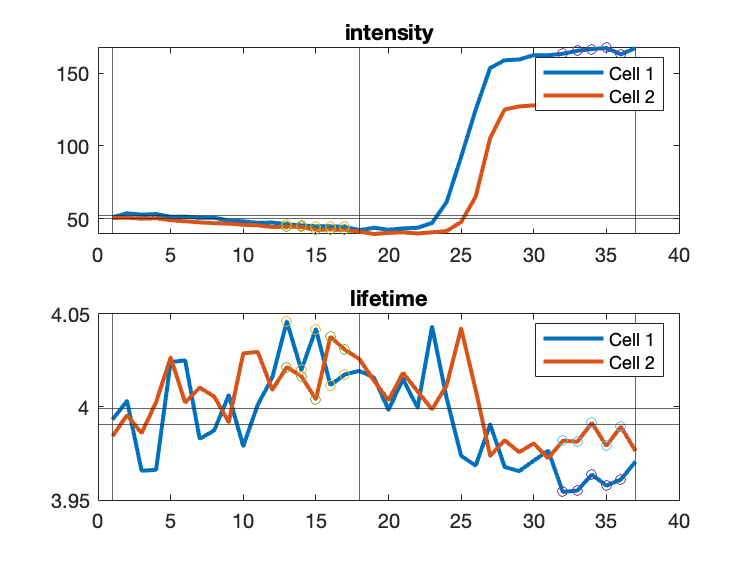

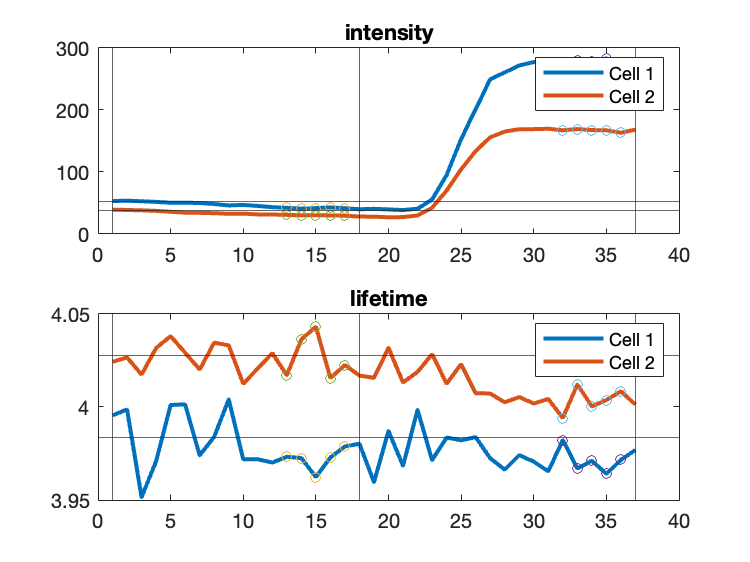

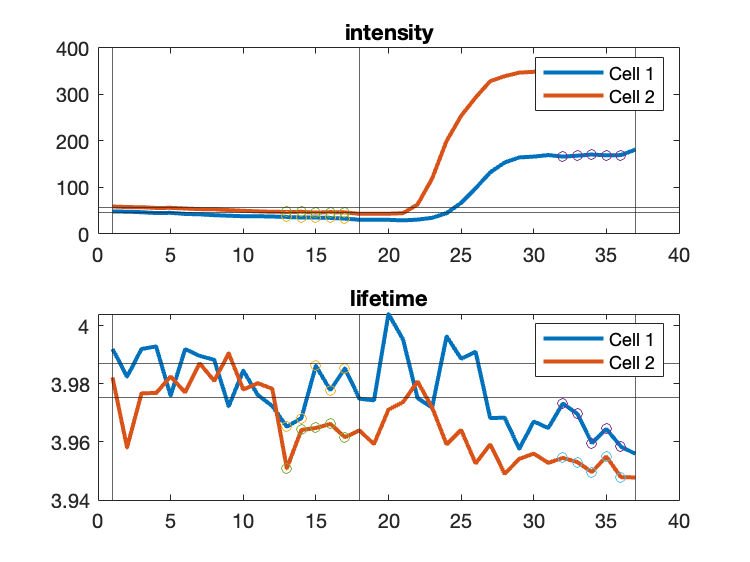

epoch_response_intensity_norm_all = 1×3 cell array
    {2×2 double}    {2×2 double}    {2×2 double}


epoch_response_lft_norm_all = 1×3 cell array
    {2×2 double}    {2×2 double}    {2×2 double}


epoch_response_intensity_all = 1×3 cell array
    {2×2 double}    {2×2 double}    {2×2 double}


epoch_response_lft_all = 1×3 cell array
    {2×2 double}    {2×2 double}    {2×2 double}



Yao_GUI_ReviseROIsBasedOnCoordinates()
CalculateROIBasedOnTopPixels(5, 0.66)
[lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels();


[epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)